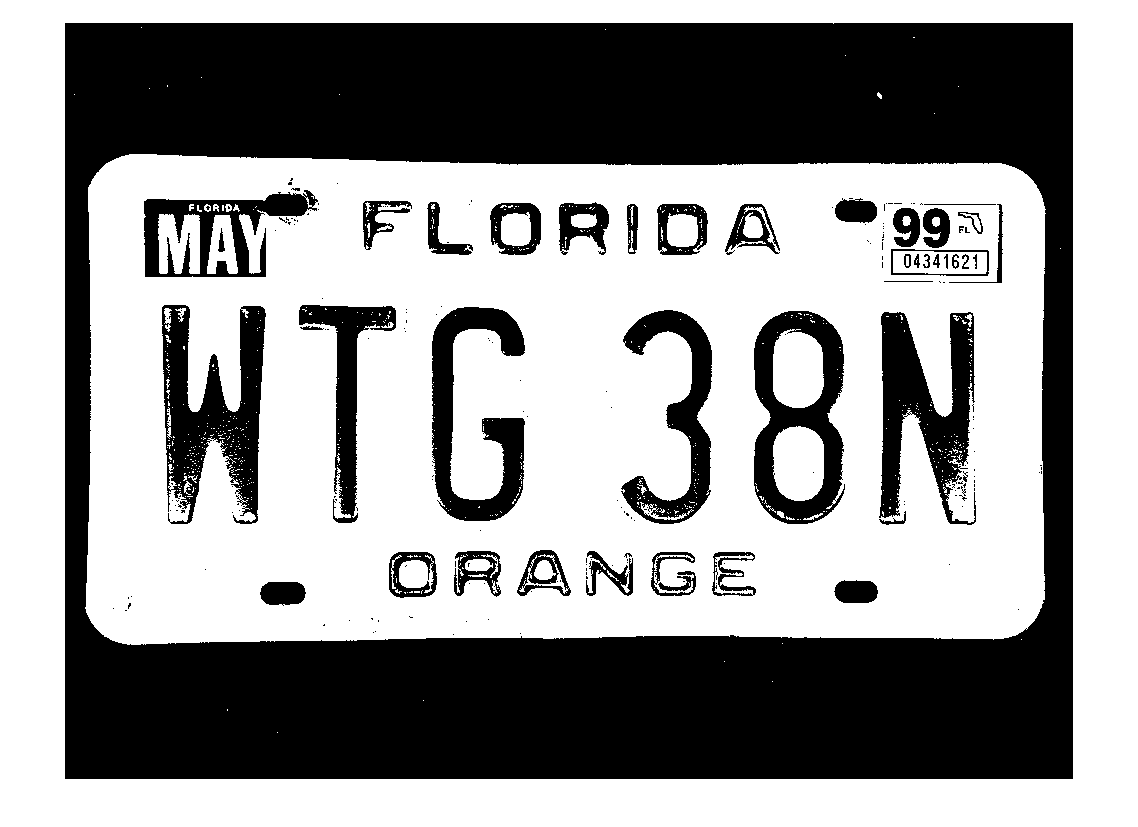


D = 'MLab/';
p = "WTG38N.jpg";

S = dir(fullfile(D,p));

for k = 1:numel(S)
    F = fullfile(D,S(k).name);
    I = imread(F);
    
    imgray = rgb2gray(I);
    I = imbinarize(imgray);
    
    I = bwareaopen(~I, 500);
    
    [h, w] = size(I);
   
    %read letter
    Iprops=regionprops(I,'BoundingBox','Area', 'Image');
    count = numel(Iprops);
    
    noPlate=[]; % Initializing the variable of number plate string.
    
    imshow(I);
    figure;
    
    for i=1:count
        
       propWidth = length(Iprops(i).Image(1,:));
       propHeight = length(Iprops(i).Image(:,1));
       
       if propWidth > 200 && propHeight > 750
           letter=readLetter(Iprops(i).Image); % Reading the letter corresponding the binary image 'N'.
           
           if letter ~= '-'
              figure; imshow(Iprops(i).Image);
              noPlate=[noPlate letter]; % Appending every subsequent character in noPlate variable.  
           end
           
       end
    end
    figure;
end 